# Longitudinal Vehicle - Main Script

## Open Model and Run Simulation

mdl = "Vehicle1D_harness_model";
if not(bdIsLoaded(mdl))
  load_system(mdl)
end

% Load default parameters
Vehicle1D_harness_setup

% Set up external input signals
vehSigBuilder = Vehicle1D_InputSignalBuilder;
inputPatterns = [
  "Constant"
  "Coastdown"
  "Brake3"
  "RoadGrade3"
  "DriveAxle"
];
numSim = numel(inputPatterns);

% Create SimulationInput object for each simulation
%simIn(1:numSim) = Simulink.SimulationInput(mdl);  % error in R2022a.
simIn(1:numSim) = Simulink.SimulationInput(char(mdl));
for idx = 1 : numSim
  inpData = feval(inputPatterns(idx), vehSigBuilder);
  simIn(idx) = setVariable(simIn(idx), "vehicle_InputSignals", inpData.Signals);
  simIn(idx) = setVariable(simIn(idx), "vehicle_InputBus", inpData.Bus);
  simIn(idx) = setModelParameter(simIn(idx), "StopTime",num2str(inpData.Options.StopTime_s));
  switch inputPatterns(idx)
  case "Coastdown"
    simIn(idx) = setVariable(simIn(idx), "initial.vehicleSpeed_kph", ...
                  inpData.Options.Coastdown.InitialVehicleSpeed_kph);
  end
end

% Run simulations
simOut = sim(simIn, "UseFastRestart","on", "ShowProgress","on");

[08-Apr-2022 13:18:51] Running simulations...
[08-Apr-2022 13:18:52] Completed 1 of 5 simulation runs
[08-Apr-2022 13:18:52] Completed 2 of 5 simulation runs
[08-Apr-2022 13:18:53] Completed 3 of 5 simulation runs
[08-Apr-2022 13:18:53] Completed 4 of 5 simulation runs
[08-Apr-2022 13:18:54] Completed 5 of 5 simulation runs


## Simulation Results

Constant


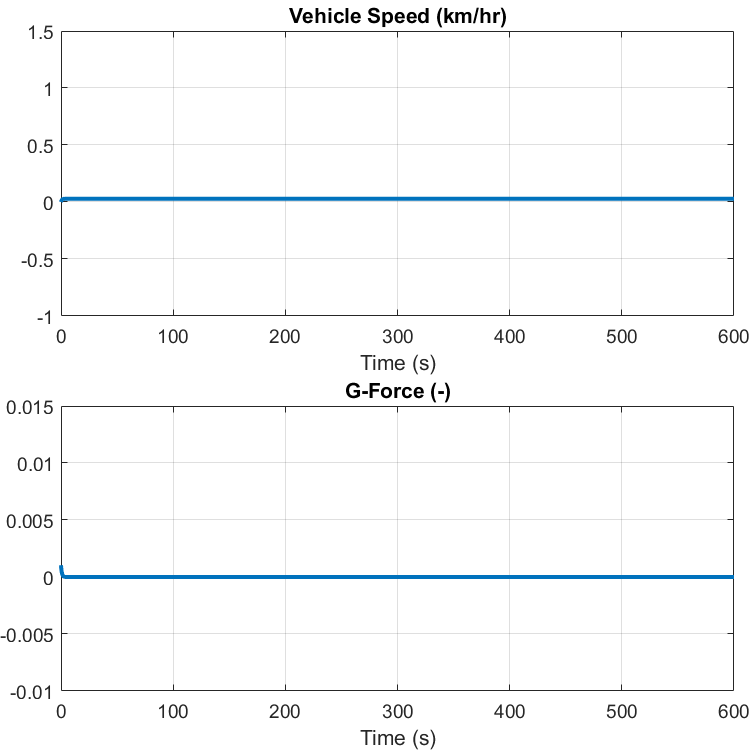

Coastdown


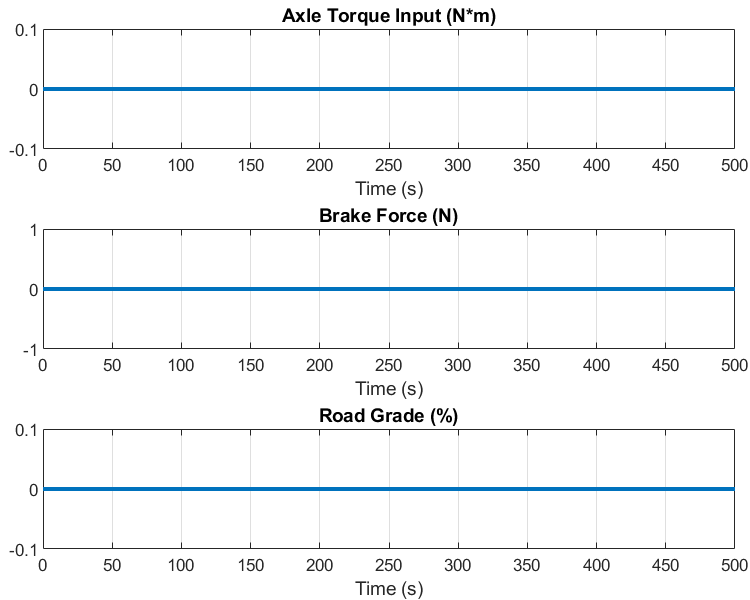

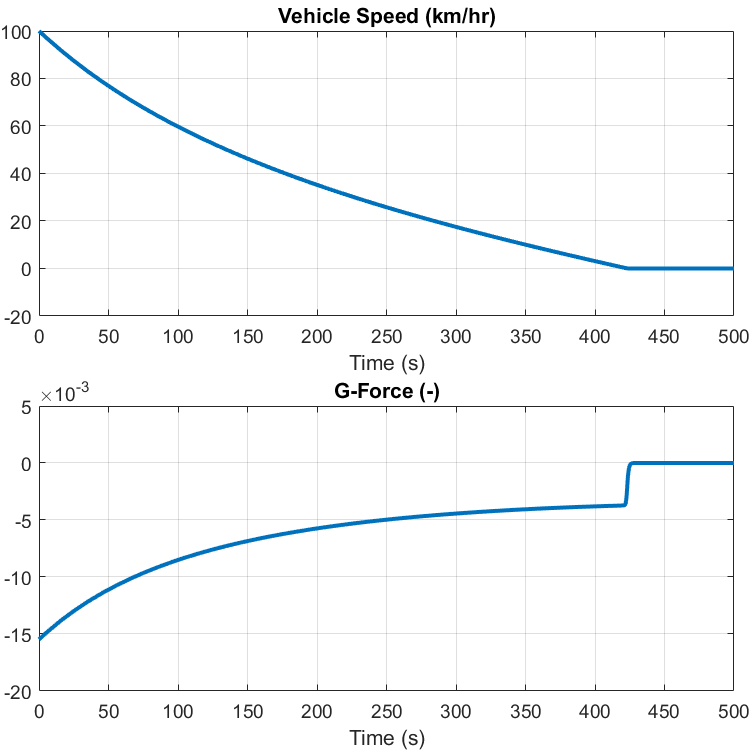

Brake3


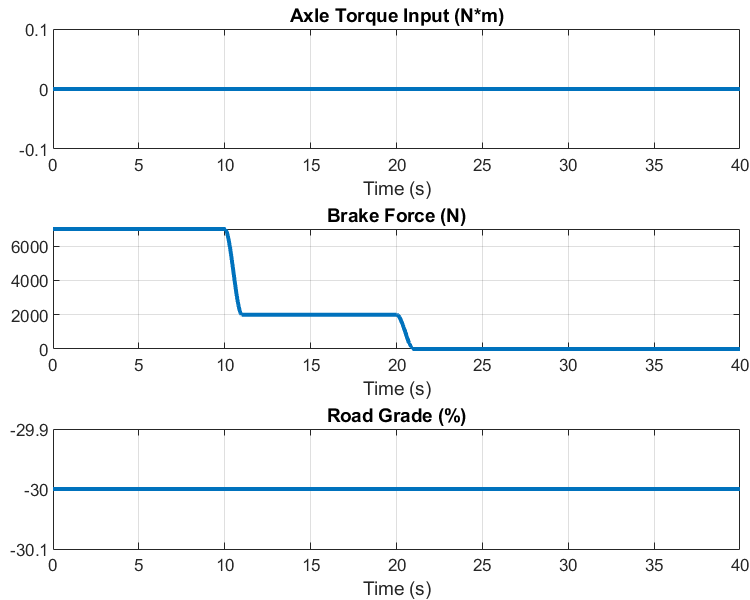

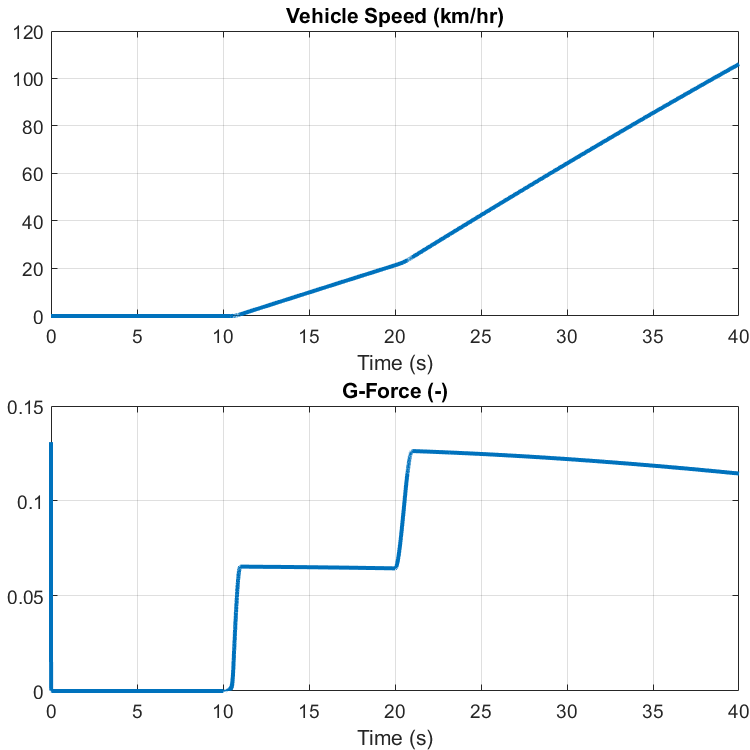

RoadGrade3


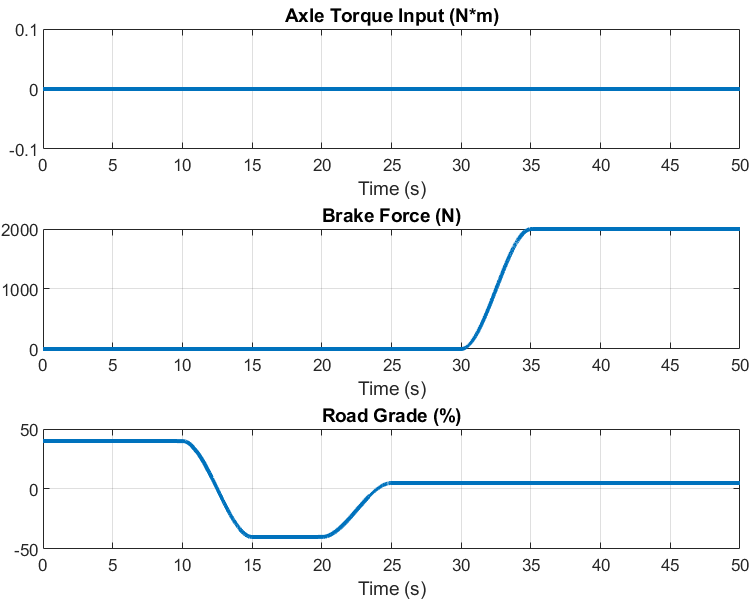

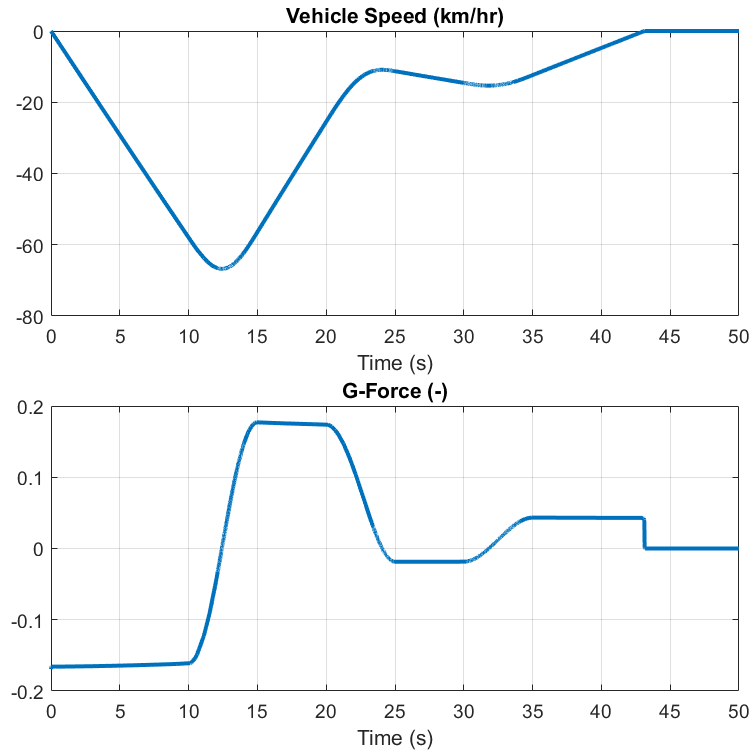

DriveAxle


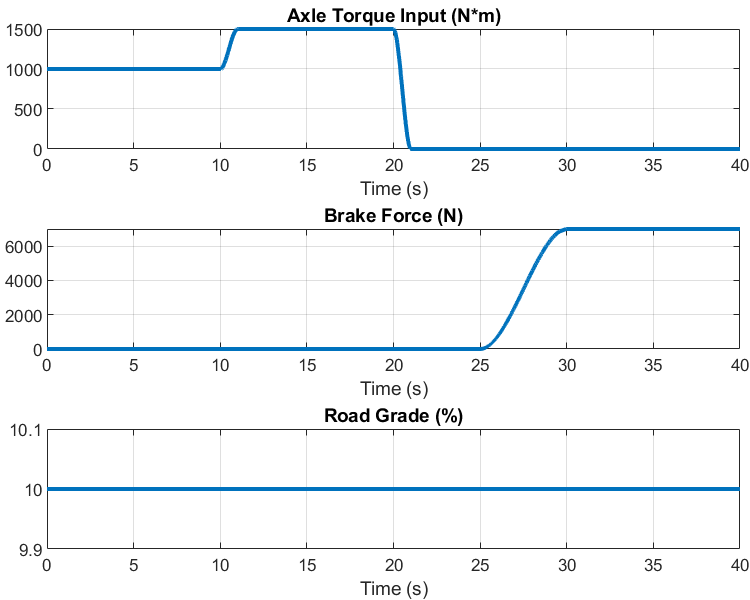

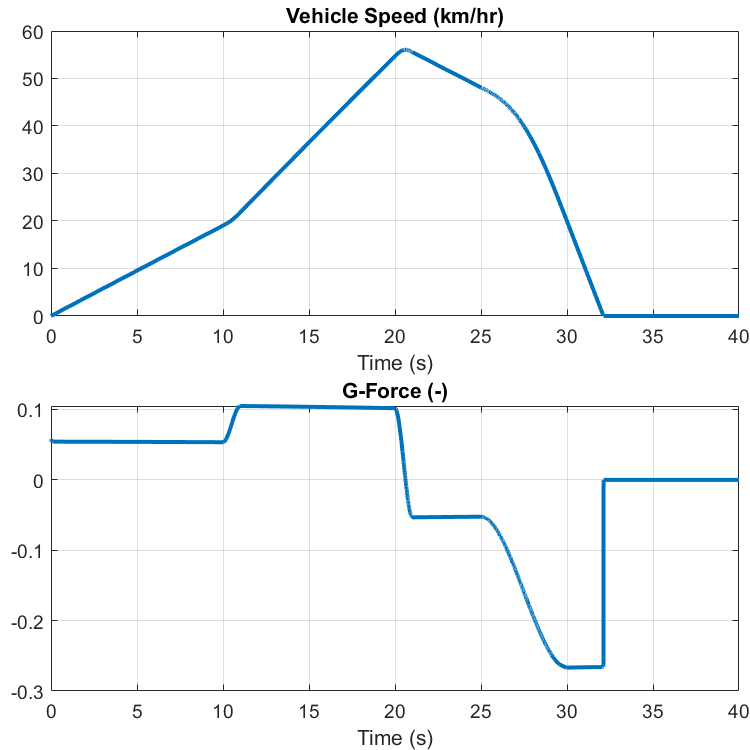

for idx = 1 : numSim
  disp(inputPatterns(idx))
  Vehicle1D_plot_results(simOut(idx).logsout)
end

*Copyright 2020-2022 The Mathworks, Inc.*